# Linear Control Design II - Group Work Problem Module 8 

## Description

Figure 1 shows an aircraft in lateral motion where the movements are yaw (rotation around the vertical axis) and roll (rotation around the longitudinal axis). The lateral motion of an aircraft takes primarily place in the horizontal plane. 

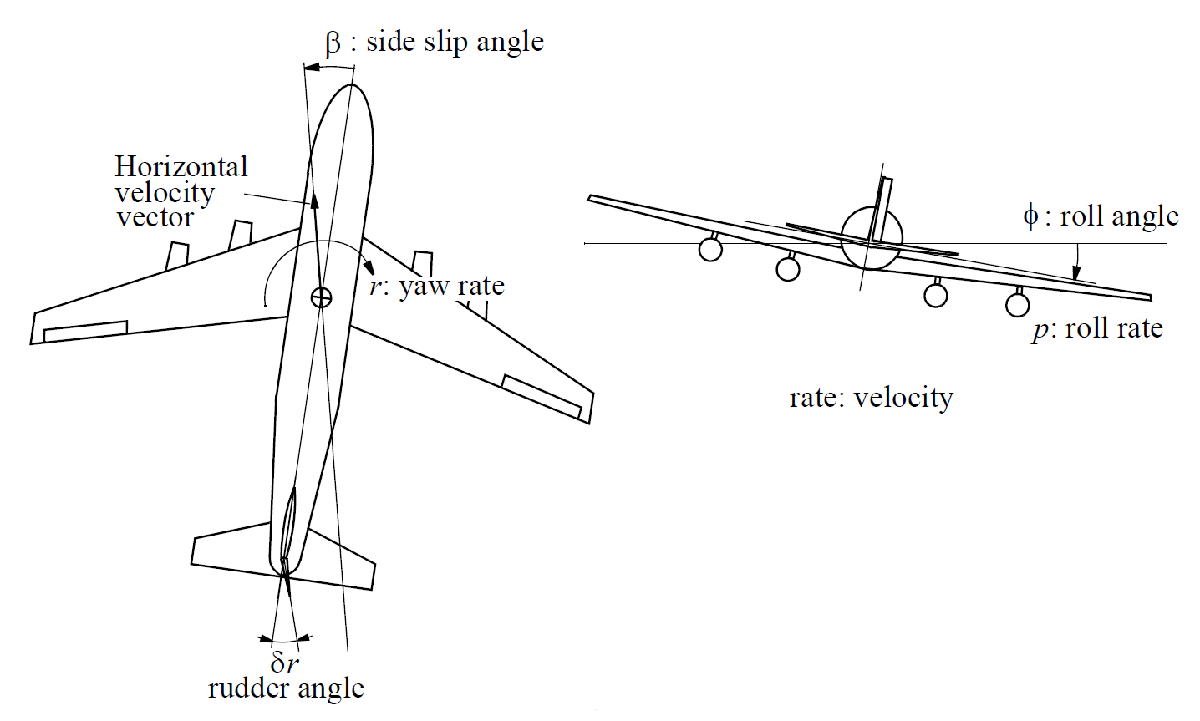  

			Figure 1: Lateral dynamics of a Boeing 747

A linearized state space model of the lateral dynamics of a Boeing 747 in altitude 40000 ft and speed 774 ft/sec (850 km/h) is shown below:

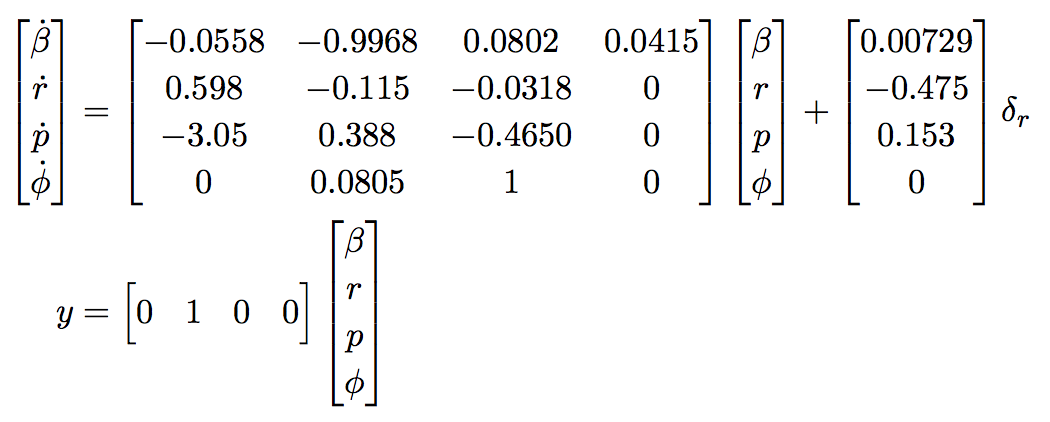

where $\beta$ is the side-slip angle (rad), $r$is the yaw rate (rad/s), $p$ is the roll rate (rad/s), $\varphi$ is the roll angle (rad), and $\delta_r$ is the rudder deflection (rad). 

% Define system matrices:
A = [-0.0558 -0.9968  0.0802  0.0415;
      0.598  -0.115  -0.0318  0;
     -3.050   0.388  -0.4650  0;
      0       0.0805  1       0]

A =    -0.0558   -0.9968    0.0802    0.0415
    0.5980   -0.1150   -0.0318         0
   -3.0500    0.3880   -0.4650         0
         0    0.0805    1.0000         0

B = [0.00729; -0.475; 0.153; 0]

B =     0.0073
   -0.4750
    0.1530
         0

C = [0 1 0 0]

C =      0     1     0     0

D = 0;

This assignment guides you through the analysis of the aircraft’s lateral dynamics in terms of natural modes and system responses to non-zero initial conditions and external inputs. 

**Problem 1** Calculate the eigenvalues of the system dynamical matrix A, and based on those identify, if relevant, the time constants, natural frequencies and damping ratios. 

% Your solution goes here:




**Problem 2** Based on the calculated eigenvalues determine the natural modes (also known as eigenmodes) of the system and plot their temporal evolution as time goes to infinitiy.

% Your solution goes here:




The eigenstructure of the lateral dynamics is usually represented by two real eigenvalues and one pair of complex conjugate eigenvalues. The three lateral modes are referred to as ***roll subsidence***, ***spiral*** and ***dutch roll***. 

- The **roll subsidence** **mode** is non-oscillatory and is usually decoupled from the spiral mode and from the dutch roll modes. In rolling motion the wing experiences a component of velocity normal to the wing resulting in a small increase in the angle of attack on the down- going wing and a small decrease on the up-going wing thus, generating a lift difference over the wing span. Moreover, the lift difference gives rise to a restoring roll moment represented by the roll subsidence mode. 

- The **spiral mode** is usually slow non-oscillatory and involves complex coupled motion in roll, yaw and side-slip angle. The spiral mode is usually excited by a disturbance in side-slip which is typically followed by a disturbance in roll. The side-slip angle generates a force on the tail fin, which in turn generates a yawing moment in the direction of the side-slip angle. The yawing motion generates increased differential lift across the wing span inducing increased roll moment and thereby, aggravates the situation. 

- The** dutch roll mode** is a damped oscillation and the motion is a complex interaction between the three lateral degrees of freedom. The dutch roll mode makes the wing tip move in an elliptic pattern seen from the side parallel to the wing. 

**Problem 3** Based on the found eigenvalues and the aforementioned modes, associate the eigenvalues to the corresponding mode of the lateral dynamics. 	

% Your solution goes here:




**Problem 4** Compute the modal matrix $\mathbf{M}_{lat}$of the system and discuss which natural modes contributes most and least to the dynamics of the state variables $\beta, r, p, \varphi$ (Make sure that your modal matrix has real elements)	

% Your solution goes here:




**Problem 5** Determine the transfer function from rudder deflection $\delta_r$ to yaw rate r, and calculate the Bode’s diagram. Which of the aforementioned modes are visible in the magnitude response of the Bode’s diagram? 		

% Your solution goes here:




**Problem 6** Calculate the zero-state response for a step of 5 degrees in the rudder input. Analyse the response in connection with the modal analysis. 	

% Your solution goes here:




**Problem 7** Calculate the zero-input response for a side-slip initial angle $\beta_0 = 1$degree. Analyse the response in connection with the modal analysis. 	

% Your solution goes here:




**Problem 8** Calculate the zero-state response for the rudder deflection shown in the figure below and discuss the aircraft’s dynamical behaviour during these manoeuvres. 

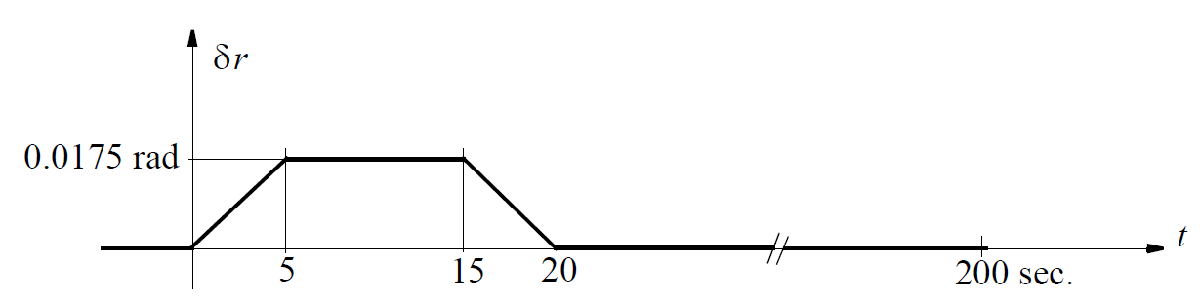

% Your solution goes here:


